f = @(x, y) y - 3*x;
g = @(x) 7*exp(x) + 3*x + 3;

y0 = 10;
x0 = 0;
xn = 3;

dx = 0.5;

x = x0 : dx : xn;
y = zeros(size(x));
y1 = zeros(size(x));
y2 = zeros(size(x));
y_exact = g(x);

y(1) = y0;
y1(1) = y0;
y2(1) = y0;

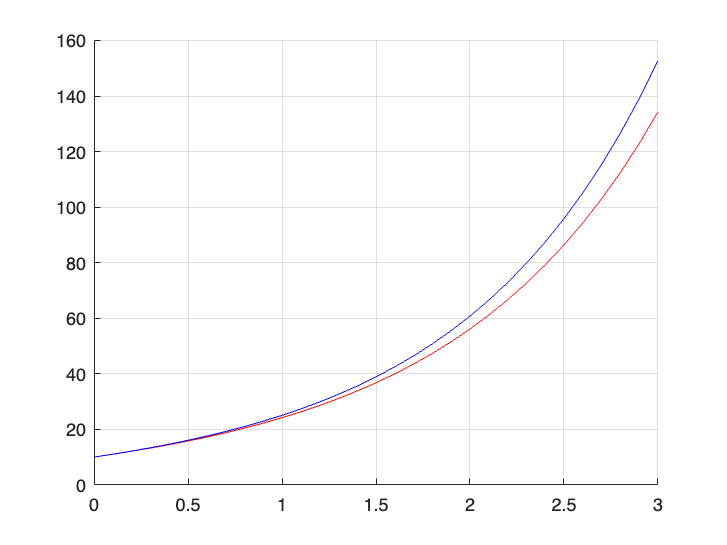

for i = 1:length(x) - 1
    y(i + 1) = y(i) + dx*(f(x(i), y(i)));
end

% This array is defined as percentage. If
% decimals wanted, remove * 100.
errors = (abs(y - y_exact)./y_exact) * 100;

% This array represents the slope given by f(x, y)
m = f(x, y);

figure;
hold on;
grid on;
plot(x, y, 'r');
plot(x, y_exact, 'b');
hold off;

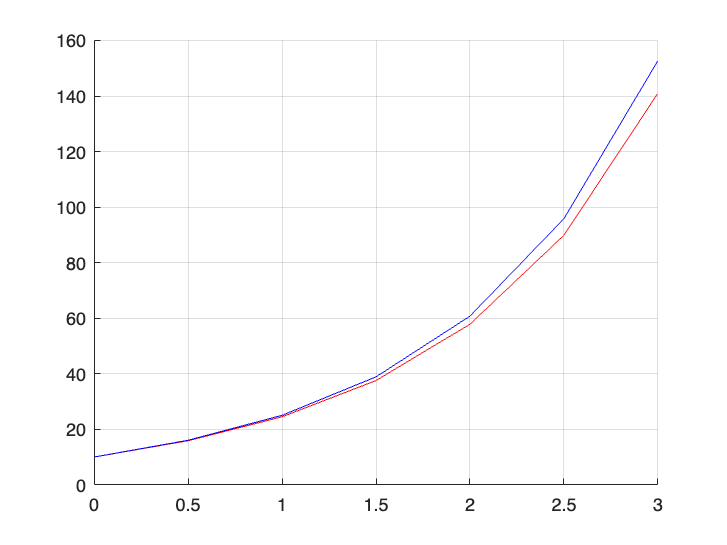

% Improving Euler's Method, 1st improvment

for i = 1:length(y) - 1
    mi = f(x(i), y(i));
    y_pred = y(i) + dx*mi;
    mf = f(x(i + 1), y_pred);

    y1(i + 1) = y(i) + dx*(mi+mf)/2;
end

% This array is defined as percentage. If
% decimals wanted, remove * 100.
errors1 = (abs(y - y_exact)./y_exact) * 100;

figure;
hold on;
grid on;
plot(x, y, 'r');
plot(x, y_exact, 'b');
hold off;

% Improving Euler's Method, 2nd improvment

for i = 1:length(y) - 1
    mi = f(x(i), y(i));
    y_pred = y(i) + (dx/2)*mi;

    m = f(( (x(i) + x(i+1))/2 ), y_pred);

    y2(i + 1) = y(i) + dx*m;
end

% This array is defined as percentage. If
% decimals wanted, remove * 100.
errors2 = (abs(y - y_exact)./y_exact) * 100;

figure;
hold on;
grid on;
plot(x, y, 'r');
plot(x, y_exact, 'b');
hold off;

figure;
hold on;
grid on;
plot(x, y, 'r');
plot(x, y_exact, 'b');
hold off;